%
n = 10;
r = 3;
m = 12*n*r;

T = 100+1;  % max iteration



% random ture solution
U_seed = sign(rand(n, r) - 0.5);
[U, ~, ~] = svds(U_seed, r);
V_seed = sign(rand(n, r) - 0.5);
[V, ~, ~] = svds(V_seed, r);

S =diag(randn(r,1));
X = U*S*V';

X = X/norm(X,'fro');

% random sensing matrix
A = normrnd(0,1,m,n^2);
y = A*X(:)/sqrt(m);

% Error Tracking
Error_Stand = zeros(T,1);

% initilzation
X0 = zeros(n,n);
for i = 1:m
    X0=X0+y(i)*reshape(A(i,:),[n,n]);
end
[U0,S0,V0] = svd(X0);
Ul = U0(:,1:r);
Sl = S0(1:r,1:r);
Vl = V0(:,1:r);

X0 = Ul*Sl*Vl';   % initialization one step hard threhold

Error_Stand(1) = norm(X0-X,'fro');

Xl = X0;


## Standard RGD

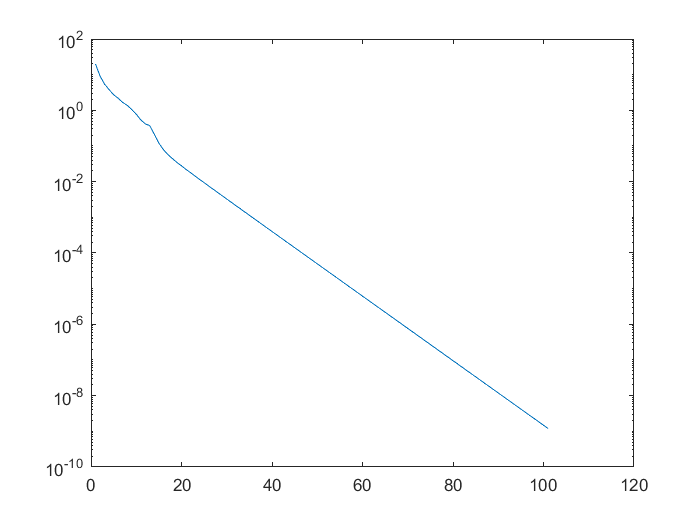

%
Xl = X0;
Ul = U0(:,1:r);
Sl = S0(1:r,1:r);
Vl = V0(:,1:r);
% standard RGD
for l = 2:T
    % compute Gl
    s = zeros(m,1);
    for i = 1:m
        s(i)= y(i)-A(i,:)*Xl(:)/sqrt(m);
    end
    Gl = zeros(n,n);
    for i = 1:m
        Gl = Gl+(1/sqrt(m))*s(i)*reshape(A(i,:),[n,n]);
    end
    
    % RGD
    [Xl_new,Ul_new,Sl_new,Vl_new] = RGD(Ul,Sl,Vl,Gl,r);
    
    % Track Errors
    Error_Stand(l) = norm(Xl_new-X,'fro');
    % Swap 
    Xl = Xl_new;
    Ul = Ul_new;
    Sl = Sl_new;
    Vl = Vl_new;
end



semilogy(Error_Stand)